# Applying the Lawler-Fujita algorithm and distortion subtraction by Gao et al. (2017) to STM images

The latter section of part 2 is unsuccessful. Undistorting the image given the displacement field is probably done not by MATLAB's imwarp() function. Alternatively, there may still be errors in my implementation of the Lawler-Fujita algorithm, particularly with the magnitude of the noise and erroneously unwrapped phase angles.

atom_diameter = 41.5;

lambda = 0.2; % [atom^-1]

Q_x = [38 37]; % [atom^-1]
Q_y = [-Q_x(2) Q_x(1)]; % just to ensure orthogonality

confidence_level = 0.9999999;

lambda = lambda*2*pi/atom_diameter;
Q_x = Q_x * 2*pi / (norm(Q_x)*atom_diameter);
Q_y = Q_y * 2*pi / (norm(Q_y)*atom_diameter);
zscore = zscorer(confidence_level);

## 1    Importing the file

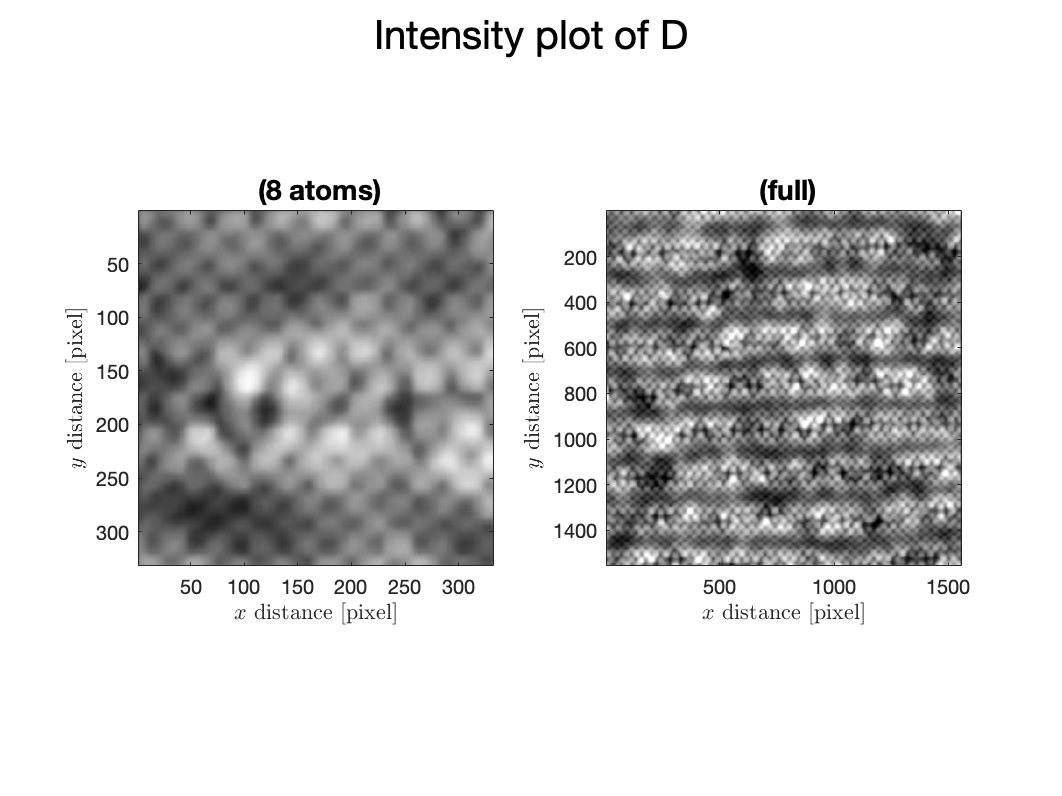

image = im2gray(imread("Figures/lawler.png"));

lattice = normies(double(image));

[image_height, image_length] = size(lattice);

comboPlot(lattice,"D",atom_diameter);

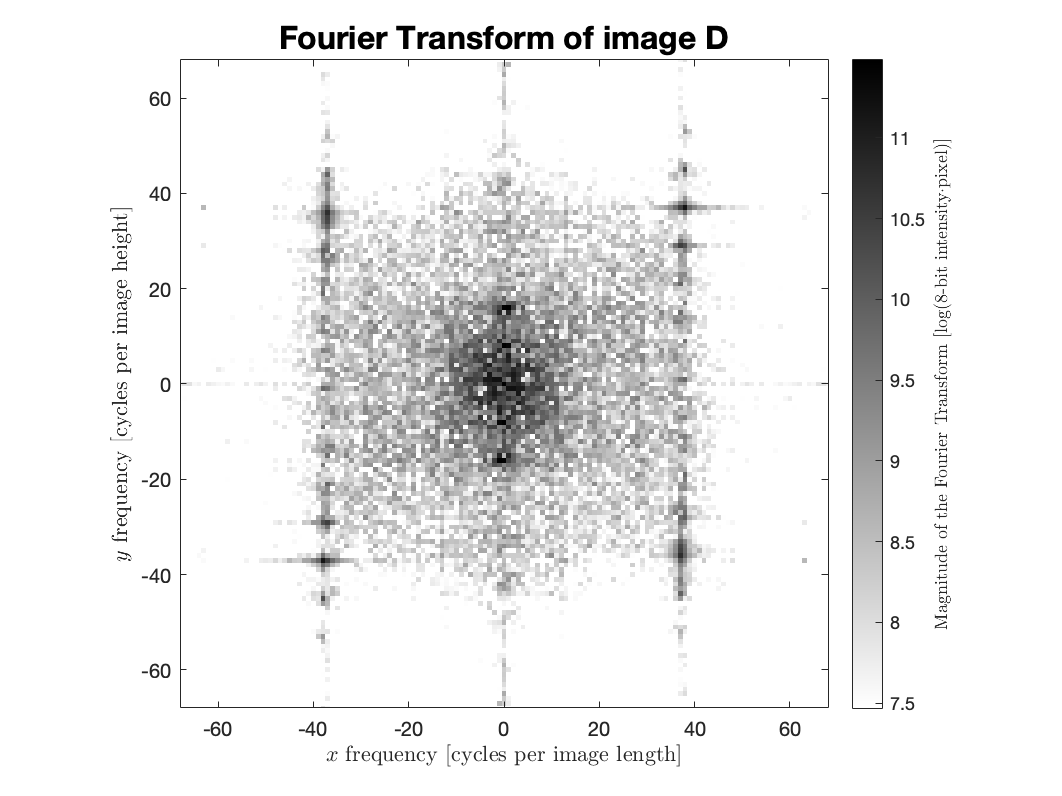

lattice_fft = myFFT(lattice,"D");
xlim([-68 68]);
ylim([-68 68]);

## 2    Calculating total distortion

Using the Lawler-Fujita algorithm, the total distortion as the sum of the imaging distortion and the physical strain, $\vec{u}_{calc}=\vec{d}+\vec{s}$, is calculated. The effects of noise and the magnitude and type of tolerable distortion could be studied using the previous and the following code.

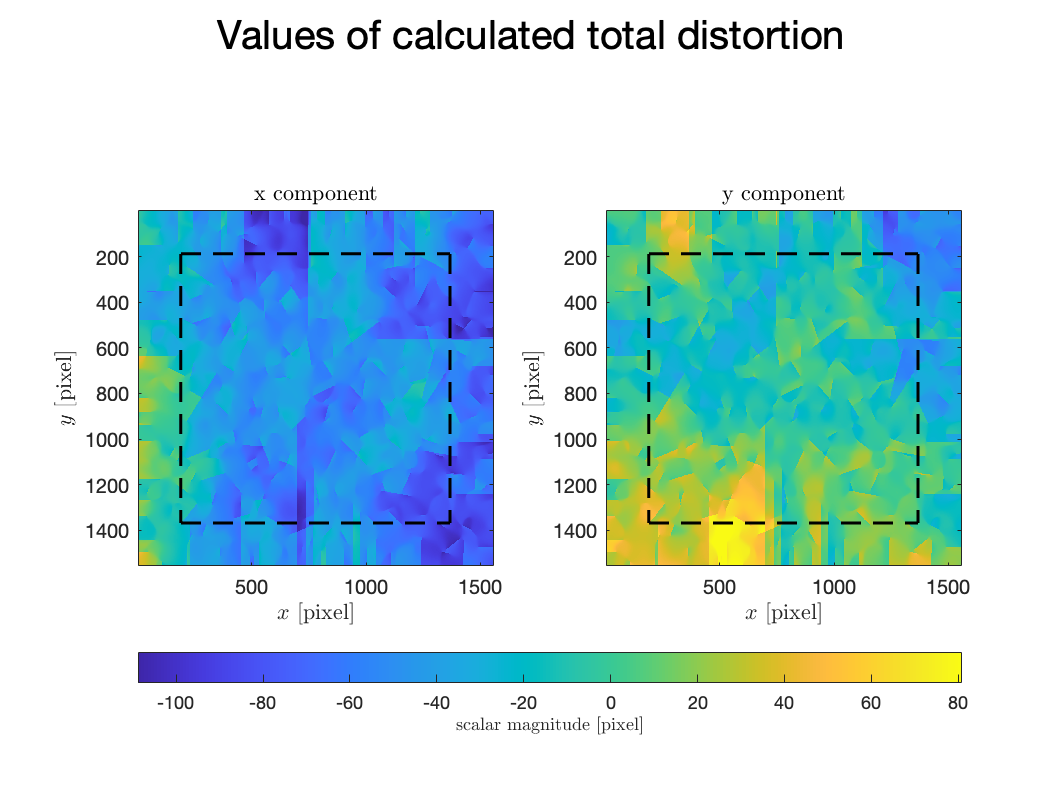

ucalc = myConv(lattice,Q_x,Q_y,lambda,zscore,true); % true as last argument to plot u_x and u_y

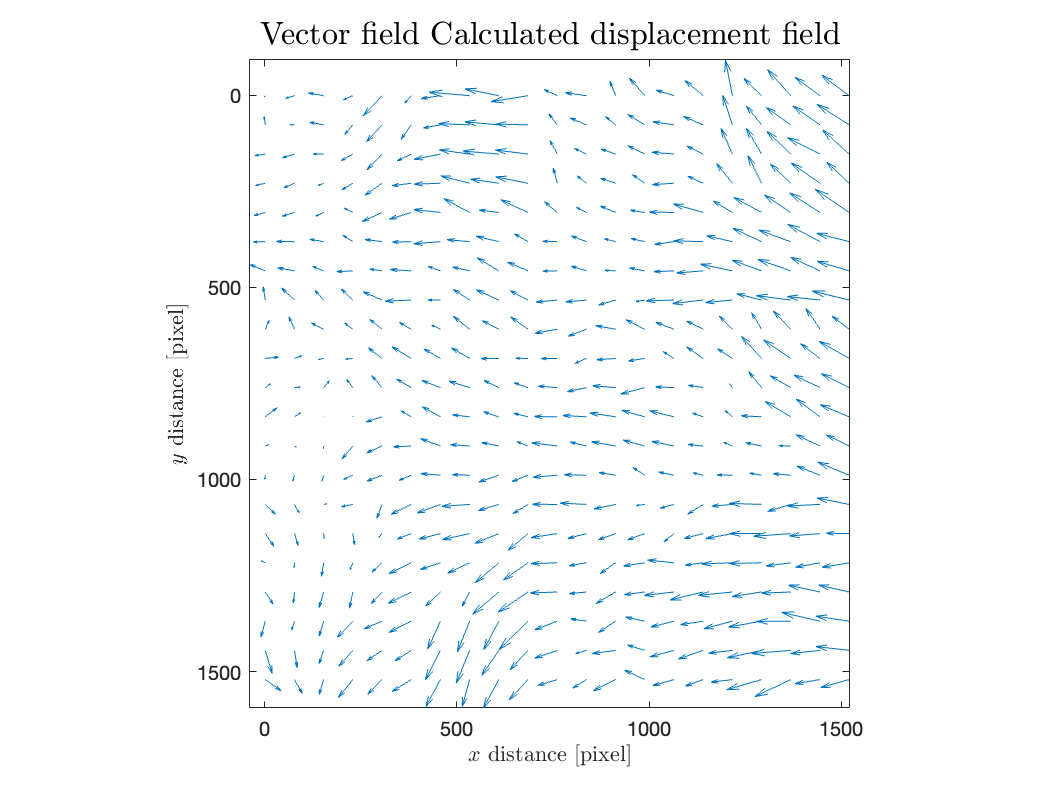


uPlot(ucalc,"Calculated displacement field");


if image_length-2*ceil(zscore/lambda)<=0 && image_height-2*ceil(zscore/lambda)<=0
    error("ERROR! No pixels without padded zeros remain.");
else
    npixel = (image_length-2*ceil(zscore/lambda))*(image_height-2*ceil(zscore/lambda));
    % the number of pixels averaged
    disp("Number of pixels averaged: " + npixel + " (" + ...
        npixel/(image_length*image_height)*100 + "%)");
end

Number of pixels averaged: 1392400 (57.5102%)



% [meanErr, stdErr] = uCompare(u,ucalc,lambda);
% disp("Error is: " + meanErr + "+/-" + stdErr*zscore + " (" + confidence_level*100 + "% confidence)");
% disp("Total error is: " + (meanErr+stdErr*zscore) + " (" + confidence_level*100 + "% confidence)");
% disp("Errors are relative unless stated otherwise.");

Try undistorting the distorted image using imwarp() and the calculated displacement field.

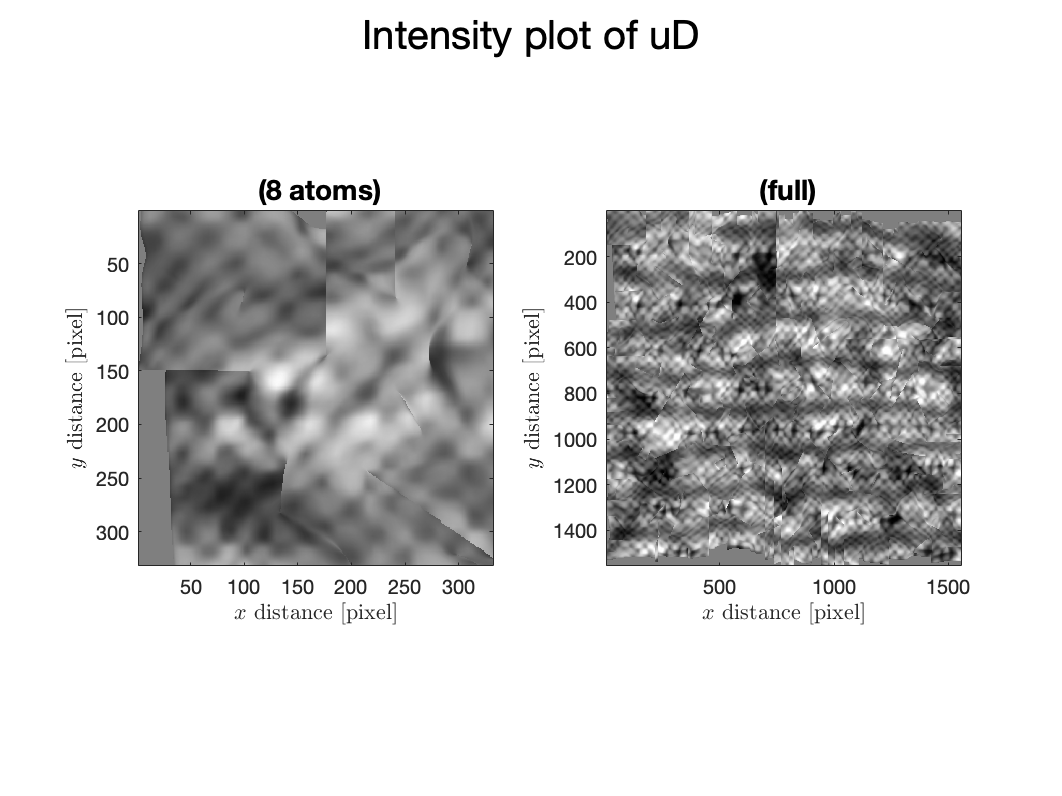

ucalc(isnan(ucalc)) = ucalc(find(isnan(ucalc))-1);
ulattice = imwarp(lattice,ucalc);
zed = ceil(zscore/lambda);
% ulattice = ulattice(zed:image_height-zed,zed:image_length-zed);
comboPlot(ulattice,"uD",atom_diameter);

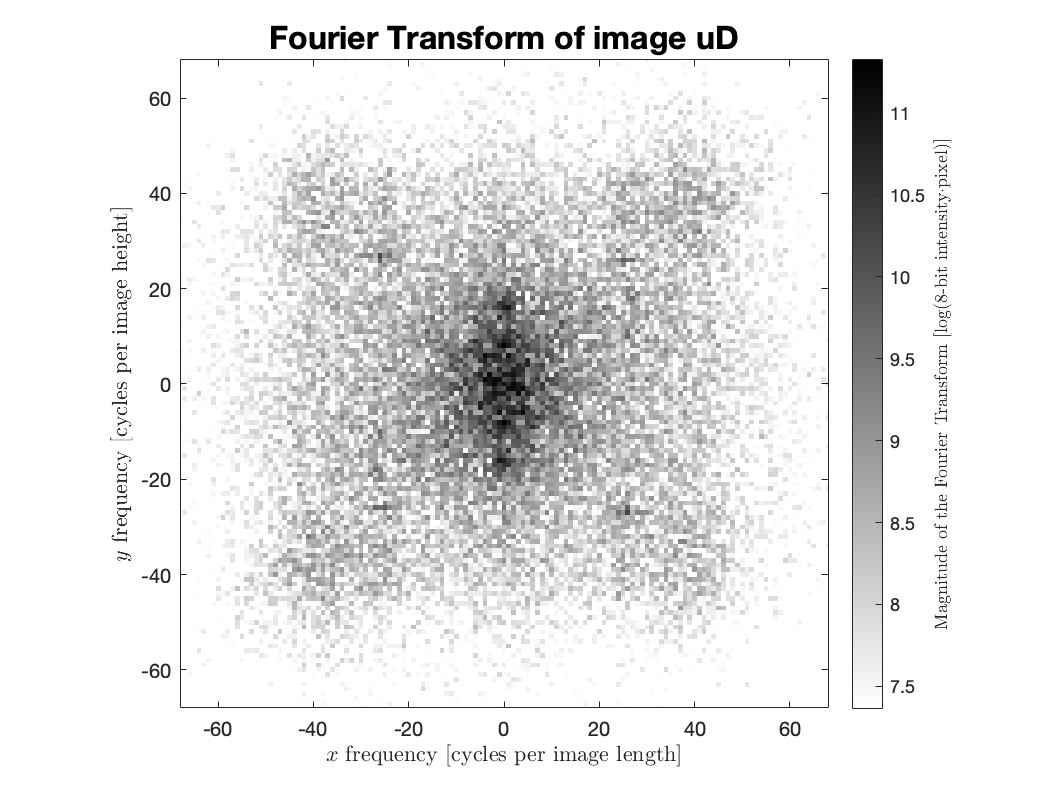

ulattice_fft = myFFT(ulattice,"uD");
xlim([-68 68]);
ylim([-68 68]);